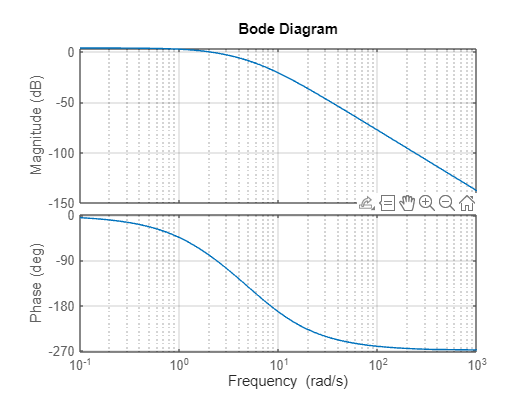

% Define the transfer function with k = 1
k = 1;
Gs = tf(127*k, conv([1, 6], conv([1, 7], [1, 2])));

% Plot the Bode plot
figure;
bode(Gs);
grid on;


% Determine the Gain Margin and the frequency
[gainMargin, phaseMargin, gmFreq, pmFreq] = margin(Gs);
fprintf('Gain Margin: %f dB at frequency %f rad/s\n', 20*log10(gainMargin), gmFreq);

Gain Margin: 17.349452 dB at frequency 8.246215 rad/s




% Define the transfer function
s = tf('s');
k = 1;
G = (127*k)/((s+6)*(s+7)*(s+2));

% Plot the Bode plot
h = bodeplot(G);
setoptions(h, 'FreqUnits', 'rad/s'); % Set frequency units to rad/s
title('Bode Plot for k = 1');
grid on;

% Enable data cursor mode
datacursormode on;

% Modify the data cursor text
dcm_obj = datacursormode(gcf);
set(dcm_obj, 'UpdateFcn', @myupdatefcn);

% Custom update function for data cursor

function txt = myupdatefcn(~, event_obj)
    % Obtain clicked position
    pos = get(event_obj, 'Position');
    freq = pos(1);
    mag_db = pos(2);

    % Display the information
    txt = {['Frequency: ', num2str(freq), ' rad/s'], ...
           ['Magnitude: ', num2str(mag_db), ' dB']};
end